# **Lab 2 **

% %Read image and check basic image properties
info = imfinfo('multidimensional.tif');
%Note how this time info is actually an array with 35 entries, this is
%becuse the multidimensional.tif file contains a 3D image with 35 planes
length(info)

ans = 35

%We can pull the relevant parameters from any page of the image file by
%indexing
info(5).Width

ans = 388

info(5).Height

ans = 269

info(5).BitDepth

ans = 16

info(5).ColorType

ans = 'grayscale'

%In order to read a 3D file, we first have to build an empty matrix of the
%same size in order to store it. For this, we can use the 'zeros' command
%which will create a matrix full of zeros of any size

%Remember that MATLAB dimensions are always in the order of rows, columns,
%pages, so we use the Height of the image as the number of rows, the Width
%as the number of columns, and the 'length' of the info vector tells us how
%many pages there are in the multidimensional.tif file. Finally we tell the
%zeros command to make this matrix out of uint16 numbers, since that's the
%data type of the original image

img = zeros(info(1).Height,info(1).Width,length(info),'uint16');
% creates a matrix, with three dimensions (rows = 269, column, pages). Any
% number between 1 to 35 should be fine 


%Reading all the pages using the FOR Loop. For a guide on FOR loops, refer to the documentation:
%https://www.mathworks.com/help/matlab/ref/for.html

for i = 1:length(info)
    img(:,:,i) = imread('multidimensional.tif',i); 
end

%load the last position (z-position) is the i slide.

%To understand what's going on here, let's break it down. A FOR loop will
%run the code between the for and end statements for a fixed number of
%iterations. The number of iterations is controlled by the length of the
%"index" variable that's defined by the for statement. In this case, we're
%naming the "index" variable as "i" and setting it equal to the range of 1
%until the length of the info variable, which is 35. So we're defining the
%variable i as a vector [1, 2, 3, ... 35]. Each iteration of the loop, the
%value of "i" will be set to the position of the vector that corresponds to
%the current iteration of the loop. So on the first iteration, i will be
%equal to 1, so the first page of the variable "img" (defined by indexing
%img(:,:,i)) will be set to the image read from the first page of the tif
%file by imread('multidimensional.tif',1). The 2nd iteration, i will be 2,
%and so on until the 35th iteration, after which the for loop will end.

size(img)

ans =    269   388    35


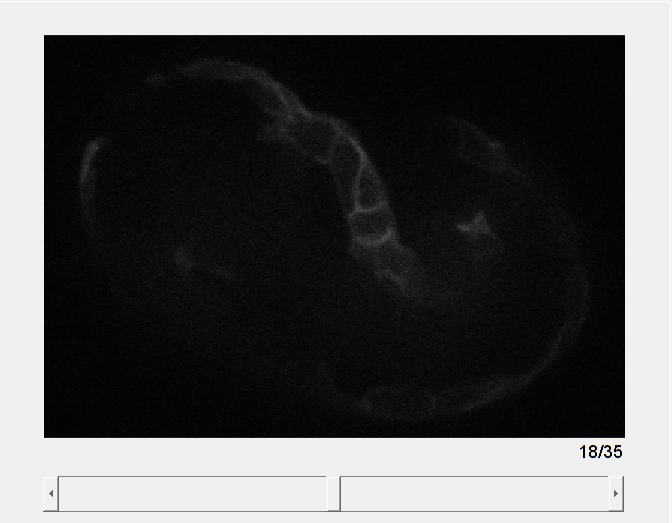

ans =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 18
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [1546 6235]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


%What if we want to have an interactive view that allows us to easily move
%through each individual page in the image? For this we can use the

imagesc(img(:,:,1)) % display specific page of the image 
colormap gray %legend that interprets pixel brightness
colorbar 

%sliceviewer
sliceViewer(img)

%The range of values over which the intensity is scaled can be adjusted
%using the "DisplayRange" parameter like this:
sliceViewer(img,"DisplayRange",[1700,3500])

ans =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 18
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [1700 3500]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


%Viewing one slice at a time makes it easy to see small structures that may
%be buried in a large image, but makes it hard to see the whole image all
%at once, we can play around with displaying every slice in sequence using
%subplot. In this case we have 35 images, so let's try making a 5x7 grid in
%which to display every image

%Try doing this without specifying the intensity scaling, or try playing
%around with the intensity scaling and see how that affects the displayed
%images
for i = 1:length(info)
    subplot(7,5,i);
    imagesc(img(:,:,i),[1700,3500])
    colormap gray
end

Error using axes
Cannot set property to a deleted object.

Error in subplot (line 563)
        ax = axes('Units', 'normalized', 'InnerPosition', position, ...

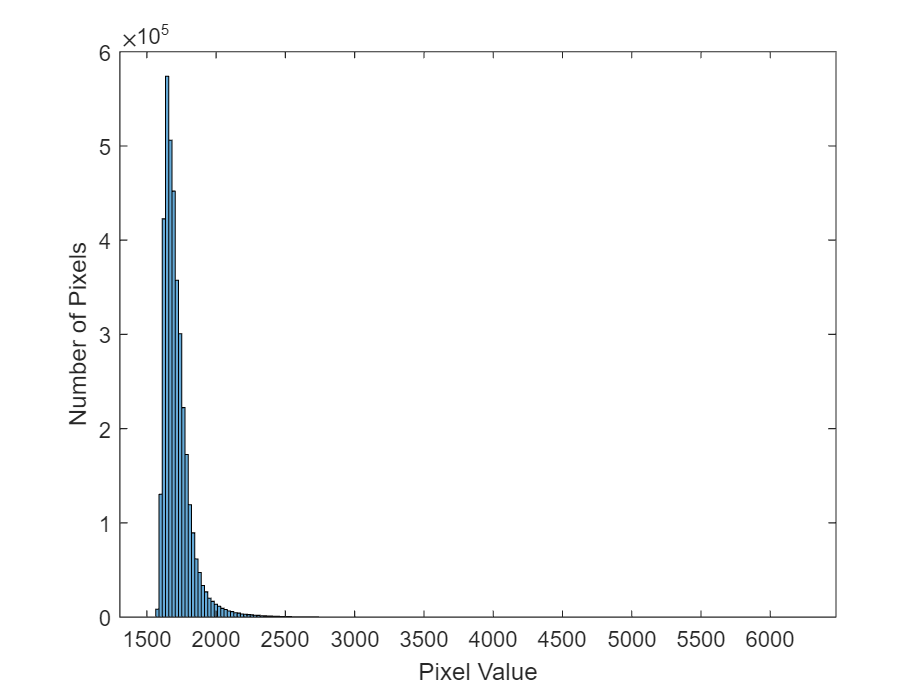

%Let's calculate Weber's contrast for this entire multi-d image. To classify foreground and
%background pixels, first generate a histogram of the whole volume and pick a
%reasonable threshold to use. 
figure;
histogram(double(img(:)),200) 
xlabel('Pixel Value')
ylabel('Number of Pixels')

% plotting whole image, previously assigned as integer, now convert value
% to float. 

%To visualize the foreground / background maps, let's apply this threshold
%and let's use
%imagesc to display a max projection of the foreground and background
%images themselves.
thresh = 1800;
foreground = img>thresh; 
%greater intensity than this threshold, brighter spots to be meaningful,
%but darker pixels to be background. 
background = img<=thresh;

%% use the histogram to find the threshold value

pixels_in_foregnd = sum(foreground(:))
% indeed higher in the foreground than background 
pixels_in_backgnd = sum(background(:))
% indeed lower than foreground 
ratio = pixels_in_foregnd/pixels_in_backgnd

%How can we see the whole image all at once? The simplest way to do this is
%what's called a max projection. In a max projection for each row and
%column, we display only the maximum intensity across all slices in 3D. We
%can use the "dim" input to the max function to calculate the 2D maximum
%image across the 3D matrix like this:
foregnd_img = img.*uint16(foreground);

max_proj_foregnd = max(foregnd_img,[],3);
figure;
imagesc(max_proj_foregnd)
colormap gray
colorbar
backgnd_img = img.*uint16(background);


max_proj_backgnd = max(backgnd_img,[],3);
figure;
imagesc(max_proj_backgnd)
colormap gray
colorbar


% Let's do Weber Contrast on the same. 
% Which will be taking mean of all the pixels in the foreground 
% in the entire volume and all the pixels in the background in 
% the entire volume.  
% Weber contrast = (I_foreground - I_background) / %I_background
mean_img_bkgnd = mean(img(background));
mean_img_fgnd = mean(img(foreground));
Weber = (mean_img_fgnd- mean_img_bkgnd)/mean_img_bkgnd

% Weber contrast should be 

% Let's try to calculate the Michelson and RMS contrast for the same. 
% (I_max - I_min) / (I_max + I_min)
max_proj = max(img,[],3);
Michelson_max_project = double(max(max_proj(:)) - min(max_proj(:)))/double(max(max_proj(:)) + min(max_proj(:)))

%values of contrast is Michelson_max_project 


% How does the Michelson calculation on max projection differs from
% calculation on the input image?
Michelson = double(max(img(:)) - min(img(:)))/double(max(img(:)) + min(img(:)))

% higher than Max Project because max is collapsing 35 images, calculate
% everything without max projection because more contrast. Lose lower
% values of pixel, the global minimum is eliminated so therefore smaller
% contrast. 

% RMS_volume = sqrt(sum(sum(sum((img - mean(img(:))).^2))))
sqrt(1/double(info(1).Width*info(1).Height)*double(sum(sum((max_proj - mean(max_proj(:))).^2))))

% But how does this compare to calculating the same metrics
% on individual slices. Let's try Weber contrast for one of them
i = 18;
img_i = img(:,:,i);
figure;
imagesc(img_i)
colormap gray
colorbar

histogram(double(img_i(:)),100)

% Calculate the Weber for the same threshold
foreground_i = img_i>1800
background_i = img_i<=1800
sum(foreground_i(:))
sum(background_i(:)) 
sum(foreground_i(:))/sum(background_i(:))
mean_backgnd_i = mean(img_i(background_i));
Weber_for_i = (mean(img_i(foreground_i))- mean_backgnd_i)/mean_backgnd_i
% See it is marginally better than the Weber contrast for the whole volume

% Additionally, try RMS on individual slice. What do you find?
sqrt(1/double(info(1).Width*info(1).Height)*double(sum(sum((img - mean(img(:))).^2))))

%each slide has contrast for RMS